FILE LOADED: The_Broadside_Wall_Seed_111.mat


        test_name: 'The Broadside Wall'
             seed: 111
          t_worst: 1.6904e+03
    max_depth_err: 0.0071
          message: 'Most violent shift at t=1690.4s | Peak depth error: 0.0071m'



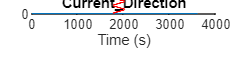

% =========================================================
% INTERACTIVE DATA VIEWER
% =========================================================

% 1. Open a UI window to select a specific .mat test file
[file, path] = uigetfile('*.mat', 'Select a Test Data File');

if isequal(file, 0)
    disp('File selection canceled.');
else
    % Load the selected file into a temporary structure
    fullpath = fullfile(path, file);
    test_data = load(fullpath);
    
    % 2. Display the Test Metrics
    fprintf('\n==================================================\n');
    fprintf('FILE LOADED: %s\n', file);
    fprintf('==================================================\n');
    
    if isfield(test_data, 'test_metrics')
        disp(test_data.test_metrics);
    else
        disp('No test_metrics struct found in this file.');
    end
    
    % 3. Dynamically find all available signals to plot
    sim_out = test_data.dummy_out;
    available_signals = {};
    
    % Get a list of everything stored in the simulation output
    sim_vars = sim_out.who;
    
    % Check for signals in 'logsout' (your Scopes)
    if ismember('logsout', sim_vars)
        log_vars = sim_out.logsout.getElementNames;
        available_signals = [available_signals; log_vars];
    end
    
    % Check for signals in 'yout' (your root Outports like the current direction)
    if ismember('yout', sim_vars)
        yout_vars = sim_out.yout.getElementNames;
        available_signals = [available_signals; yout_vars];
    end
    
    % 4. Open a UI window to select which signals to plot
    if isempty(available_signals)
        disp('No logged signals found in the selected file.');
    else
        [selected_indices, tf] = listdlg('PromptString', {'Select signals to plot:', '(Hold Ctrl or Shift to select multiple)'}, ...
                                         'SelectionMode', 'multiple', ...
                                         'ListString', available_signals, ...
                                         'Name', 'Signal Selector', ...
                                         'ListSize', [250, 300]);
        
        if tf
            % --- Visual Time Range Selector ---
            range_choice = questdlg('How would you like to view the time range?', ...
                'Time Range Selection', ...
                'Full Simulation', 'Select Visually', 'Full Simulation');
            
            t_bounds = []; % Default to empty
            
            if strcmp(range_choice, 'Select Visually')
                % Use the first selected signal as a preview trace
                preview_sig_name = available_signals{selected_indices(1)};
                try
                    preview_sig = sim_out.logsout.get(preview_sig_name);
                catch
                    preview_sig = sim_out.yout.get(preview_sig_name);
                end
                
                % Create a temporary figure
                prev_fig = figure('Name', 'Select Time Window', 'NumberTitle', 'off');
                plot(preview_sig.Values.Time, preview_sig.Values.Data, 'LineWidth', 1.5, 'Color', [0.5 0.5 0.5]);
                grid on; hold on;
                title(sprintf('PREVIEW: %s\nClick TWICE to set start and end times.', preview_sig_name), 'Interpreter', 'none');
                xlabel('Time (s)');
                
                % Drop a reference line so you know where the event happened
                if isfield(test_data, 'test_metrics')
                    if isfield(test_data.test_metrics, 't_worst')
                        xline(test_data.test_metrics.t_worst, 'r--', 'Worst Shift', 'LineWidth', 2);
                    elseif isfield(test_data.test_metrics, 't_complete') && ~isnan(test_data.test_metrics.t_complete)
                        xline(test_data.test_metrics.t_complete, 'g--', 'Settled', 'LineWidth', 2);
                    end
                end
                
                % Grab 2 points from the user
                [x_clicks, ~] = ginput(2);
                t_bounds = sort(x_clicks); 
                close(prev_fig);
            end

            % 5. Plot the selected 2D signals
            num_plots = length(selected_indices);
            figure('Name', ['Telemetry: ', file], 'NumberTitle', 'off', 'Position', [100, 100, 800, 200*num_plots]);
            tiledlayout('flow', 'TileSpacing', 'compact');
            
            ax = gobjects(num_plots, 1);
            
            for i = 1:num_plots
                sig_name = available_signals{selected_indices(i)};
                
                try
                    sig_obj = sim_out.logsout.get(sig_name);
                catch
                    sig_obj = sim_out.yout.get(sig_name);
                end
                
                t_array = sig_obj.Values.Time;
                data_array = sig_obj.Values.Data;
                
                ax(i) = nexttile;
                plot(t_array, data_array, 'LineWidth', 1.5);
                
                if size(data_array, 2) > 1
                    legend('Actual', 'Reference', 'Location', 'best');
                end
                
                title(sig_name, 'Interpreter', 'none'); 
                xlabel('Time (s)');
                grid on;
                
                if ~isempty(t_bounds)
                    xlim(t_bounds);
                end
                
                hold on;
                if isfield(test_data, 'test_metrics')
                    if isfield(test_data.test_metrics, 't_worst')
                        xline(test_data.test_metrics.t_worst, 'r--', 'Worst Shift', 'LabelVerticalAlignment', 'bottom');
                    elseif isfield(test_data.test_metrics, 't_complete') && ~isnan(test_data.test_metrics.t_complete)
                        xline(test_data.test_metrics.t_complete, 'g--', 'Settled', 'LabelVerticalAlignment', 'bottom');
                    end
                end
                hold off;
            end
            linkaxes(ax, 'x');
            
           % =========================================================
            % 6. 3D TRAJECTORY PLOT
            % =========================================================
            do_3d = questdlg('Would you like to generate a 3D Trajectory Plot?', ...
                '3D Trajectory', 'Yes', 'No', 'No');
                
            if strcmp(do_3d, 'Yes')
                [xyz_indices, tf_xyz] = listdlg('PromptString', {'Select X, Y, and Z signals:', '(Must select exactly 3)'}, ...
                                                 'SelectionMode', 'multiple', ...
                                                 'ListString', available_signals, ...
                                                 'Name', '3D Signal Selector');
                                                 
                if tf_xyz && length(xyz_indices) == 3
                    figure('Name', ['3D Trajectory: ', file], 'NumberTitle', 'off', 'Position', [150, 150, 700, 600]);
                    
                    xyz_data = cell(1,3);
                    
                    for k = 1:3
                        sig_name = available_signals{xyz_indices(k)};
                        try
                            sig_obj = sim_out.logsout.get(sig_name);
                        catch
                            sig_obj = sim_out.yout.get(sig_name);
                        end
                        
                        t_array_3d = sig_obj.Values.Time;
                        d_array = sig_obj.Values.Data;
                        
                        % Clean up matrices (take actual state, ignore reference if grouped)
                        if size(d_array, 2) > 1
                            d_array = d_array(:, 1);
                        end
                        
                        % Apply the same time bounds selected earlier
                        if ~isempty(t_bounds)
                            valid_idx = (t_array_3d >= t_bounds(1)) & (t_array_3d <= t_bounds(2));
                            xyz_data{k} = d_array(valid_idx);
                        else
                            xyz_data{k} = d_array;
                        end
                    end
                    
                    % Generate 3D Plot
                    plot3(xyz_data{1}, xyz_data{2}, xyz_data{3}, 'b-', 'LineWidth', 2);
                    grid on; hold on;
                    
                    % Mark Start (Green Circle) and End (Red Square)
                    plot3(xyz_data{1}(1), xyz_data{2}(1), xyz_data{3}(1), 'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g');
                    plot3(xyz_data{1}(end), xyz_data{2}(end), xyz_data{3}(end), 'rs', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
                    
                    title('AUV 3D Trajectory', 'Interpreter', 'none');
                    xlabel(available_signals{xyz_indices(1)}, 'Interpreter', 'none');
                    ylabel(available_signals{xyz_indices(2)}, 'Interpreter', 'none');
                    zlabel(available_signals{xyz_indices(3)}, 'Interpreter', 'none');
                    
                    % --- NEW: Cubic Bounding Box Logic ---
                    % 1. Find min and max for each axis
                    min_x = min(xyz_data{1}); max_x = max(xyz_data{1});
                    min_y = min(xyz_data{2}); max_y = max(xyz_data{2});
                    min_z = min(xyz_data{3}); max_z = max(xyz_data{3});
                    
                    % 2. Calculate the center of the trajectory
                    center_x = (max_x + min_x) / 2;
                    center_y = (max_y + min_y) / 2;
                    center_z = (max_z + min_z) / 2;
                    
                    % 3. Find the longest dimension (max range)
                    ranges = [max_x - min_x, max_y - min_y, max_z - min_z];
                    max_range = max(ranges);
                    
                    % 4. Add a 5% buffer so the data doesn't touch the box edges
                    padded_range = max_range * 1.05;
                    
                    % 5. Apply the new limits uniformly around the center
                    xlim([center_x - padded_range/2, center_x + padded_range/2]);
                    ylim([center_y - padded_range/2, center_y + padded_range/2]);
                    zlim([center_z - padded_range/2, center_z + padded_range/2]);
                    % -------------------------------------
                    
                    % Invert Z-axis so depth goes down
                    set(gca, 'ZDir', 'reverse');
                    
                    
                    legend('Trajectory', 'Start', 'End', 'Location', 'best');
                    hold off;
                    
                elseif tf_xyz
                    disp('You must select exactly 3 signals for a 3D plot.');
                end
            end
            
        else
            disp('Plotting canceled.');
        end
    end
end